# Make a Feature Table

Neurotechnology, Brains and Machines 2023 (shell code my Sam Michalka)

This notebook will help you write functions to extract features from your EMG data and put them into a feature table. It is valuable to put this feature extraction process into a function so that you can be sure to run the same processes on your train and test data.

First, load the data you want to work with. This code will expect that you have data in a 3 dimension matrix with the dimensions: channels (electrodes)  x  timepoints (measurements in a trial)  x trials (one attempt at rock, paper, or scissors).

clear
label_rps = string(["rock","paper","scissors"]);
load("R1R2FilteredAll.mat")
Fs = 1000;

Now, extract the features and put them into a variable. The code to do this will be in a function below (or you can move it into a separate function that is in the same folder).

We will make a list of the names of features to include.

includedFeatures = {'var','mean', 'mode', 'median', 'range', 'std', 'mad'}; 

Then extract those features. This code extracts the features for each channel separately unless you write an exception to this rule.

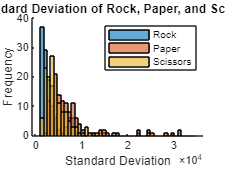

feature_table = extractFeatures(R1R2trainChTimeTr,includedFeatures,Fs, R1R2traingesturelist, label_rps);

% feature_table = extractFeatures(R1R2testChTimeTr,includedFeatures,Fs, R1R2testgesturelist, label_rps);

Save your features in a .mat file so you can load them later to do ML without recalculating them.

Change these file names!

save("R1R2training_table_stuff.mat","feature_table","R1R2traingesturelist");
% save("R1R2test_table_stuff.mat","feature_table","R1R2testgesturelist");

# Feature extraction code

This is where the magic happens. It takes in your data and outputs a table of features with labels.

function [feature_table] = extractFeatures(dataChTimeTr,includedFeatures, Fs, labels, label_rps)
    
    % List of channels to include (can change to only use some)
    includedChannels = 1:size(dataChTimeTr,1);
    
    % Empty feature table
    feature_table = table();

    
    for f = 1:length(includedFeatures)

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Calcuate feature values for 
        % fvalues should have rows = number of trials
        % usually fvales will have coluns = number of channels (but not if
        % it is some comparison between channels)
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        % Check the name of each feature and hop down to that part of the
        % code ("case" is like... in the case that it is this thing.. do
        % this code)
        switch includedFeatures{f}

            % Variance  
            % variance represents the average squared deviation of the
            % signal from the mean. In this case, the signal is all of the
            % timepoints for a single channel and trial.
            %(fvalues = trials x channels)
            case 'var'
                fvalues = squeeze(var(dataChTimeTr,0,2))';
            case 'mean'
                fvalues = squeeze(mean(dataChTimeTr, 2))';
            case 'median'
                fvalues = squeeze(median(dataChTimeTr, 2))';
            case 'mode'
                fvalues = squeeze(mode(dataChTimeTr, 2))';
            case 'range'
                fvalues = squeeze(mode(dataChTimeTr, 2))';
            case 'std'
                fvalues = squeeze(std(dataChTimeTr,0,2))';
            case 'mad'
                fvalues = squeeze(mad(dataChTimeTr,0,2))';
            % case 'wl'
            %     fvalues = squeeze(jWaveformLength(dataChTimeTr, 2))
            % case 'ssc'
            %     fvalues = squeeze(jSlopeSignChange(dataChTimeTr))
            % case 'zc'
            %     fvalues = squeeze(jZeroCrossing(dataChTimeTr))
             
            % Write your own options here by using case 'option name'
            % 'myawesomefeature'
                % my awesome feature code that outputs fvalues


            otherwise
                % If you don't recognize the feature name in the cases
                % above
                disp(strcat('unknown feature: ', includedFeatures{f},', skipping....'))
                break % This breaks out of this round of the for loop, skipping the code below that's in the loop so you don't include this unknown feature
        end

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Put feature values (fvalues) into a table with appropriate names
        % fvalues should have rows = number of trials
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        % If there is only one feature, just name it the feature name
        if size(fvalues,2) == 1
            feature_table = [feature_table table(fvalues,...
                'VariableNames',string(strcat(includedFeatures{f})))];
        
        % If the number of features matches the number of included
        % channels, then assume each column is a channel
        elseif size(fvalues,2) == length(includedChannels)
            %Put data into a table with the feature name and channel number
            for  ch = includedChannels
                feature_table = [feature_table table(fvalues(:,ch),...
                    'VariableNames',string(strcat(includedFeatures{f}, '_' ,'Ch',num2str(ch))))]; %#ok<AGROW>
            end
        
        
        else
        % Otherwise, loop through each one and give a number name 
            for  v = 1:size(fvalues,2)
                feature_table = [feature_table table(fvalues(:,v),...
                    'VariableNames',string(strcat(includedFeatures{f}, '_' ,'val',num2str(v))))]; %#ok<AGROW>
            end
        end
    end

feature_array = table2array(feature_table);
numCond = length(label_rps);


    c = 1;
    var_data1(1,:) = feature_table.var_Ch1(c == labels)';
    mean_data1(1,:) = feature_table.mean_Ch1(c == labels)';
    mode_data1(1,:) = feature_table.mode_Ch1(c == labels)';
    median_data1(1,:) = feature_table.median_Ch1(c == labels)';
    range_data1(1,:) = feature_table.range_Ch1(c == labels)';
    std_data1(1,:) = feature_table.std_Ch1(c == labels)';
    mad_data1(1,:) = feature_table.mad_Ch1(c == labels)';

    c = 2;
    var_data2(1,:) = feature_table.var_Ch1(c == labels)';
    mean_data2(1,:) = feature_table.mean_Ch1(c == labels)';
    mode_data2(1,:) = feature_table.mode_Ch1(c == labels)';
    median_data2(1,:) = feature_table.median_Ch1(c == labels)';
    range_data2(1,:) = feature_table.range_Ch1(c == labels)';
    std_data2(1,:) = feature_table.std_Ch1(c == labels)';
    mad_data2(1,:) = feature_table.mad_Ch1(c == labels)';

    c = 3;
    var_data3(1,:) = feature_table.var_Ch1(c == labels)';
    mean_data3(1,:) = feature_table.mean_Ch1(c == labels)';
    mode_data3(1,:) = feature_table.mode_Ch1(c == labels)';
    median_data3(1,:) = feature_table.median_Ch1(c == labels)';
    range_data3(1,:) = feature_table.range_Ch1(c == labels)';
    std_data3(1,:) = feature_table.std_Ch1(c == labels)';
    mad_data3(1,:) = feature_table.mad_Ch1(c == labels)';

    % figure(1)
    % hold on
    % var_bins = 0:4*10^7:10^9;
    % var_hist1 = histogram(var_data1(1,:), 'BinEdges', var_bins);
    % var_hist2 = histogram(var_data2(1,:), 'BinEdges', var_bins);   
    % var_hist3 = histogram(var_data3(1,:), 'BinEdges', var_bins);   
    % legend('Rock', 'Paper', 'Scissors')
    % xlabel("Variance")
    % ylabel("Frequency")
    % title("Variance of Rock, Paper, and Scissors")
    % hold off

    % figure(2)
    % hold on
    % mean_bins = -1.5*10^3:20:-10^3;
    % histogram(mean_data1(1,:), 'BinEdges', mean_bins);
    % histogram(mean_data2(1,:), 'BinEdges', mean_bins);   
    % histogram(mean_data3(1,:), 'BinEdges', mean_bins);   
    % legend('Rock', 'Paper', 'Scissors')
    % xlabel("Mean")
    % ylabel("Frequency")
    % title("Mean of Rock, Paper, and Scissors")
    % hold off
    % 
    % figure(3)
    % hold on
    % mode_bins = -2.5*10^5:10^4:-10^4;
    % histogram(mode_data1(1,:), 'BinEdges', mode_bins);
    % histogram(mode_data2(1,:), 'BinEdges', mode_bins);   
    % histogram(mode_data3(1,:), 'BinEdges', mode_bins);   
    % legend('Rock', 'Paper', 'Scissors')
    % xlabel("Mode")
    % ylabel("Frequency")
    % title("Mode of Rock, Paper, and Scissors")
    % hold off
    % 
    % figure(4)
    % hold on
    % median_bins = -1.5*10^3:50:-500;
    % histogram(median_data1(1,:), 'BinEdges', median_bins);
    % histogram(median_data2(1,:), 'BinEdges', median_bins);   
    % histogram(median_data3(1,:), 'BinEdges', median_bins);   
    % legend('Rock', 'Paper', 'Scissors')
    % xlabel("Median")
    % ylabel("Frequency")
    % title("Median of Rock, Paper, and Scissors")
    % hold off
    % 
    % figure(5)
    % hold on
    % range_bins = -3*10^5:10^4:0;
    % histogram(range_data1(1,:), 'BinEdges', range_bins);
    % histogram(range_data2(1,:), 'BinEdges', range_bins);   
    % histogram(range_data3(1,:), 'BinEdges', range_bins);   
    % legend('Rock', 'Paper', 'Scissors')
    % xlabel("Range")
    % ylabel("Frequency")
    % title("Range of Rock, Paper, and Scissors")
    % hold off
    % 
    % figure(6)
    std_bins = 10^3:750:3.5*10^4;
    hold on
    histogram(std_data1(1,:), 'BinEdges', std_bins);
    histogram(std_data2(1,:), 'BinEdges', std_bins);   
    histogram(std_data3(1,:), 'BinEdges', std_bins);   
    legend('Rock', 'Paper', 'Scissors')
    xlabel("Standard Deviation")
    ylabel("Frequency")
    title("Standard Deviation of Rock, Paper, and Scissors")
    hold off
end
